# Motion control SPLINES

Andrés Holguín Restrepo

2023-1

clear
close all

ni=9;
nf=30;



t = linspace(0,2*pi,ni);
tf=linspace(t(1),t(end),nf)

tf =              0          0.22          0.43          0.65          0.87          1.08          1.30          1.52          1.73          1.95          2.17          2.38          2.60          2.82          3.03          3.25          3.47          3.68          3.90          4.12          4.33          4.55          4.77          4.98          5.20          5.42          5.63          5.85          6.07          6.28


x = 1+sin(t).*0.5.*exp(-t./2/pi);
y = 1+cos(t).*0.5.*exp(-t./2/pi);
z = (2*pi-t)/2/pi+0.5;
xx=spline(t,x,tf);
yy=spline(t,y,tf);
zz=spline(t,z,tf);
format bank
data=[(1:30)' xx' yy' zz']

data =           1.00          1.00          1.50          1.50
          2.00          1.11          1.47          1.47
          3.00          1.20          1.42          1.43
          4.00          1.27          1.36          1.40
          5.00          1.33          1.28          1.36
          6.00          1.37          1.20          1.33
          7.00          1.39          1.11          1.29
          8.00          1.39          1.02          1.26
          9.00          1.37          0.94          1.22
         10.00          1.34          0.86          1.19


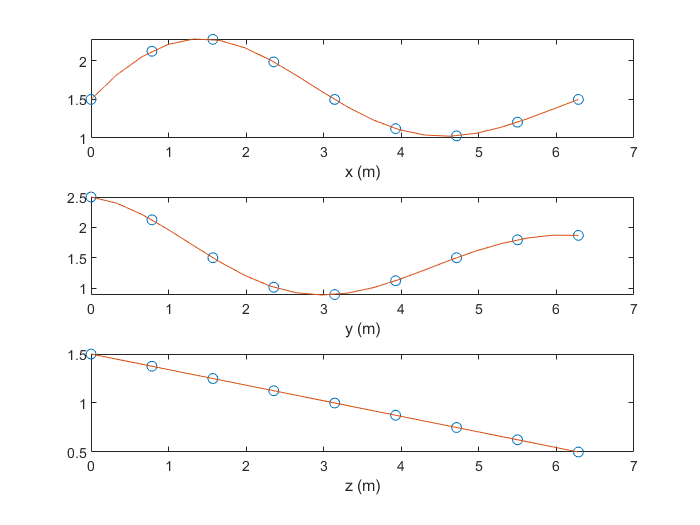


figure()

subplot(3,1,1)
plot(t,x,'o',tf,xx)
xlabel("x (m)")
subplot(3,1,2)
plot(t,y,'o',tf,yy)
xlabel("y (m)")
subplot(3,1,3)
plot(t,z,'o',tf,zz)
xlabel("z (m)")

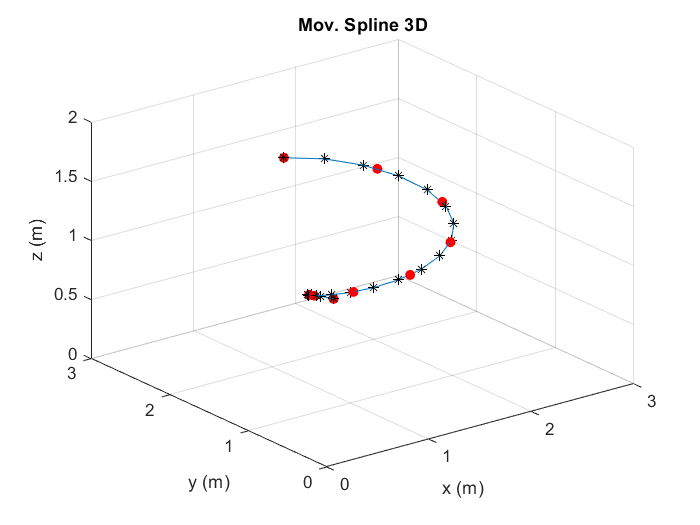


figure()
%line(x,y,z,'Color','red','LineStyle','--')

scatter3(x,y,z,'filled',"o","MarkerFaceColor","red")
hold on
scatter3(xx,yy,zz,"*","black")
line(xx,yy,zz)
hold off
xlabel("x (m)");
ylabel("y (m)");
zlabel("z (m)");
view(120,50);
grid on
title("Mov. Spline 3D")
hold off
view(3)
axis([0 3 0 3 0 2]);

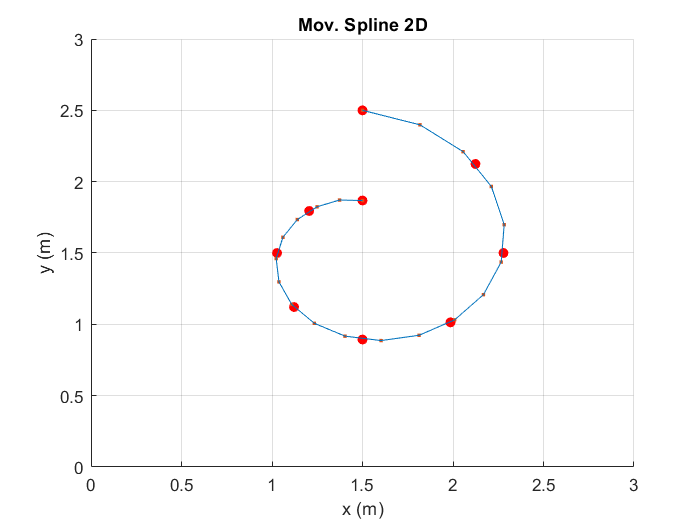

figure()
scatter(x,y,'filled',"o","MarkerFaceColor","red")
hold on
scatter(xx,yy,".","MarkerFaceColor","black")
line(xx,yy)
hold off
xlabel("x (m)");
ylabel("y (m)");
axis([0 3 0 3]);
grid on
title("Mov. Spline 2D")


pp = spline(t,sqrt(x.^2+y.^2))

pp = struct with fields:
      form: 'pp'
    breaks: [0 0.79 1.57 2.36 3.14 3.93 4.71 5.50 6.28]
     coefs: [8×4 double]
    pieces: 8.00
     order: 4.00
       dim: 1.00


rhoSPLINE = ppval(pp, linspace(0,2*pi,101))

rhoSPLINE =           2.92          2.94          2.96          2.98          2.99          3.00          3.01          3.02          3.02          3.02          3.02          3.01          3.01          3.00          2.99          2.97          2.96          2.94          2.92          2.90          2.87          2.85          2.82          2.79          2.76          2.73          2.69          2.66          2.62          2.58          2.54          2.50          2.46          2.42          2.38          2.34          2.29          2.25          2.21          2.16          2.12          2.08          2.04          2.00          1.96          1.92          1.88          1.84          1.81          1.78


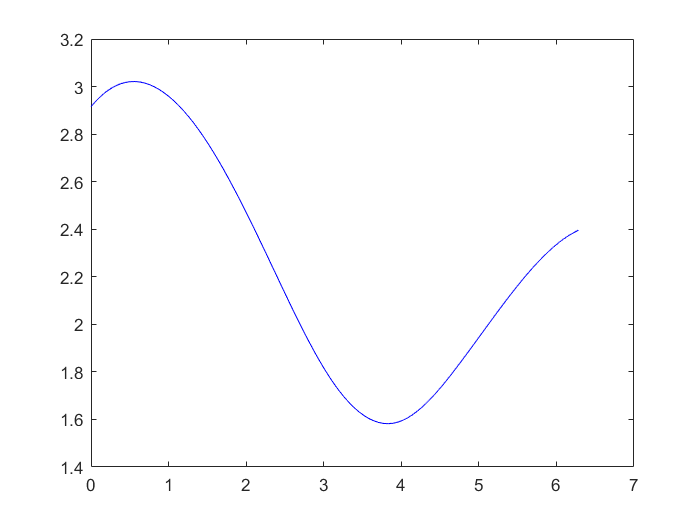

plot(linspace(0,2*pi,101),rhoSPLINE,'-b')

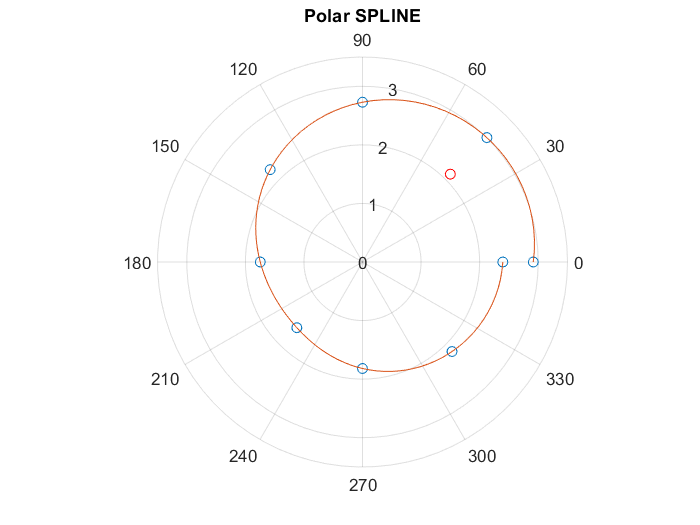

polarplot(t,sqrt(x.^2+y.^2),'o')
hold on
polarplot(linspace(0,2*pi,101),rhoSPLINE)
polarplot(pi/4,1.5*sqrt(2),'r-o')
hold off
title("Polar SPLINE")

### Tipos de interpolación

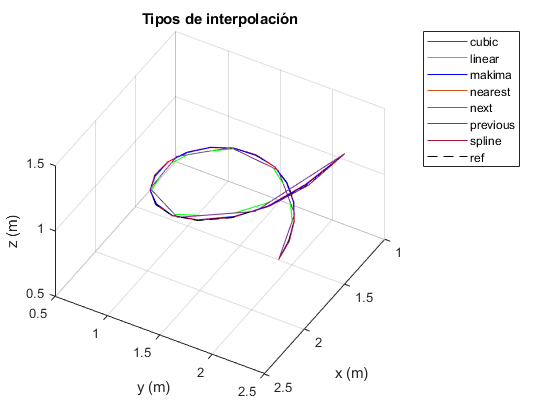

figure()
line(interp1(t,x,tf,"cubic"),interp1(t,y,tf,"cubic"),interp1(t,z,tf,"cubic"),'Color','red','LineWidth',0.25)
hold on
line(interp1(t,x,tf,"linear"),interp1(t,y,tf,"linear"),interp1(t,z,tf,"linear"),'Color','green','LineWidth',0.25)
line(interp1(t,x,tf,"makima"),interp1(t,y,tf,"makima"),interp1(t,z,tf,"makima"),'Color','blue','LineWidth',0.25)
line(interp1(t,x,tf,"nearest"),interp1(t,y,tf,"nearest"),interp1(t,z,tf,"nearest"),'Color','#D95319','LineWidth',0.25)
line(interp1(t,x,tf,"next"),interp1(t,y,tf,"next"),interp1(t,z,tf,"next"),'Color','magenta','LineWidth',0.25)
line(interp1(t,x,tf,"previous"),interp1(t,y,tf,"previous"),interp1(t,z,tf,"previous"),'Color','#7E2F8E','LineWidth',0.25)
line(interp1(t,x,tf,"spline"),interp1(t,y,tf,"spline"),interp1(t,z,tf,"spline"),'Color','#A2142F','LineWidth',0.25)
plot3(1.5+sin(tf).*exp(-tf./2/pi),1.5+cos(tf).*exp(-tf./2/pi),(2*pi-tf)/2/pi+0.5,"k--")
hold off
view(120,50);
xlabel("x (m)");
ylabel("y (m)");
zlabel("z (m)");
title("Tipos de interpolación")
legend("cubic","linear","makima","nearest","next","previous","spline","ref")
grid on

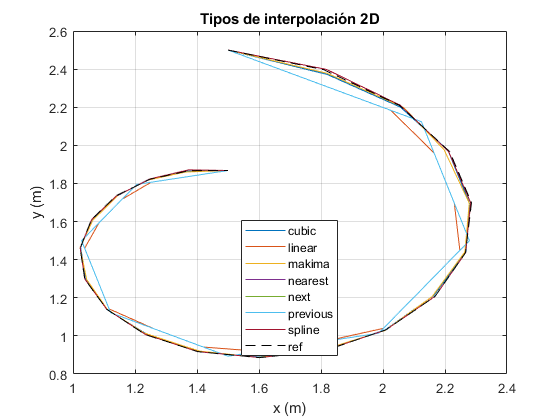


figure()
plot(interp1(t,x,tf,"cubic"),interp1(t,y,tf,"cubic"))
hold on
plot(interp1(t,x,tf,"linear"),interp1(t,y,tf,"linear"))
plot(interp1(t,x,tf,"makima"),interp1(t,y,tf,"makima"))
plot(interp1(t,x,tf,"nearest"),interp1(t,y,tf,"nearest"))
plot(interp1(t,x,tf,"next"),interp1(t,y,tf,"next"))
plot(interp1(t,x,tf,"previous"),interp1(t,y,tf,"previous"))
plot(interp1(t,x,tf,"spline"),interp1(t,y,tf,"spline"))
plot(1.5+sin(tf).*exp(-tf./2/pi),1.5+cos(tf).*exp(-tf./2/pi),"k--")
hold off
xlabel("x (m)");
ylabel("y (m)");

title("Tipos de interpolación 2D")
legend("cubic","linear","makima","nearest","next","previous","spline","ref","Location","best")
%legend("cubic","spline")
grid on

## SOLUCIÓN MAYA_UN

H=3

H = 3

D=4

D = 4

delta=0.3

delta = 0.3000


[L0,L1,L2,L3,thetas]=soluciones(xx,yy,zz,H,D,delta);

## SIMULACIÓN MAYA_UN

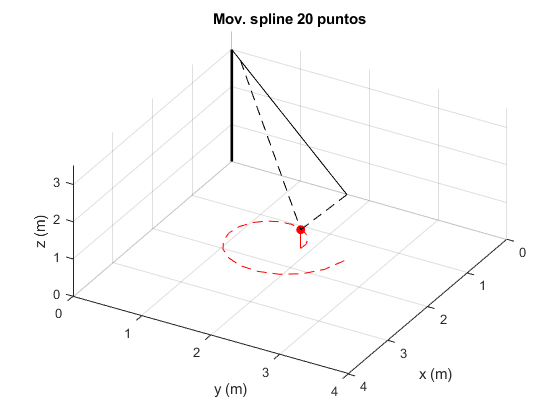

figure()
for i=1:length(xx)
    clf
    stem3(xx(i),yy(i),zz(i),"ro",'filled')
    line(xx(1:i),yy(1:i),'Color','red','LineStyle','--')
    line(L0(:,1,i),L0(:,2,i),L0(:,3,i),'Color','black','LineWidth',2)
    line(L1(:,1,i),L1(:,2,i),L1(:,3,i),'Color','black')
    line(L2(:,1,i),L2(:,2,i),L2(:,3,i),'Color','black','LineStyle','--')
    line(L3(:,1,i),L3(:,2,i),L3(:,3,i),'Color','black','LineStyle','--')
    view(120,50);
    axis([0 4 0 4 0 3.5]);
    xlabel("x (m)");
    ylabel("y (m)");
    zlabel("z (m)");
    grid on
    title("Mov. spline 20 puntos")
    %w = waitforbuttonpress;
    F(i) = getframe(gcf) ;
    drawnow
end


writerObj = VideoWriter('Caso20p',"MPEG-4");
writerObj.FrameRate = 10;

open(writerObj);

for i=1:length(F)
    frame = F(i) ;    
    writeVideo(writerObj, frame);
end
close(writerObj);

function [L0,L1,L2,L3,thetas]=soluciones(x,y,z,H,D,delta)
    for i=1:length(x)
        [L0_i,L1_i,L2_i,L3_i,thetas_i]=solMaya(x(i),y(i),z(i),H,D,delta);
        thetas(i,:)=thetas_i;
        L0(:,:,i)=L0_i;L1(:,:,i)=L1_i;
        L2(:,:,i)=L2_i;L3(:,:,i)=L3_i;
    end
end


function [L0,L1,L2,L3,thetas]=solMaya(x,y,z,H,D,delta)
    syms theta_2 theta_3
    [theta,rho,z] = cart2pol(x,y,z);
    h=z-H;
    b=sqrt((rho-delta)^2+h^2);
    c=sqrt((rho-D)^2+h^2);
    F1=0==sin(theta_3)/b-sin(theta_2)/c;
    F2=D==delta+b*cos(theta_2)+c*cos(theta_3);
    [SolTheta_2,SolTheta_3]=vpasolve([F1;F2],[theta_2;theta_3],[pi/4,pi/4]);
    SolTheta_2=-double(SolTheta_2);
    SolTheta_3=-double(SolTheta_3);
    P0=[0,0,0];
    P1=P0+[0,0,H];
    P1_2=P1+[delta,0,0]*rotz(-theta);
    P2=P1+[D,0,0]*rotz(-theta);
    P3=P1_2+[b,0,0]*roty(SolTheta_2)*rotz(-theta);
    L0=[P0;P1];L1=[P1;P2];L2=[P1_2;P3];L3=[P2;P3];
    thetas=[theta,SolTheta_2,SolTheta_3];
end

